## Kalman Filter with Linear System Model

In this example we use Kalman filter on a linear discrete system models identified with a wizard that comes with Matlab System Identification Toolbox add-in.

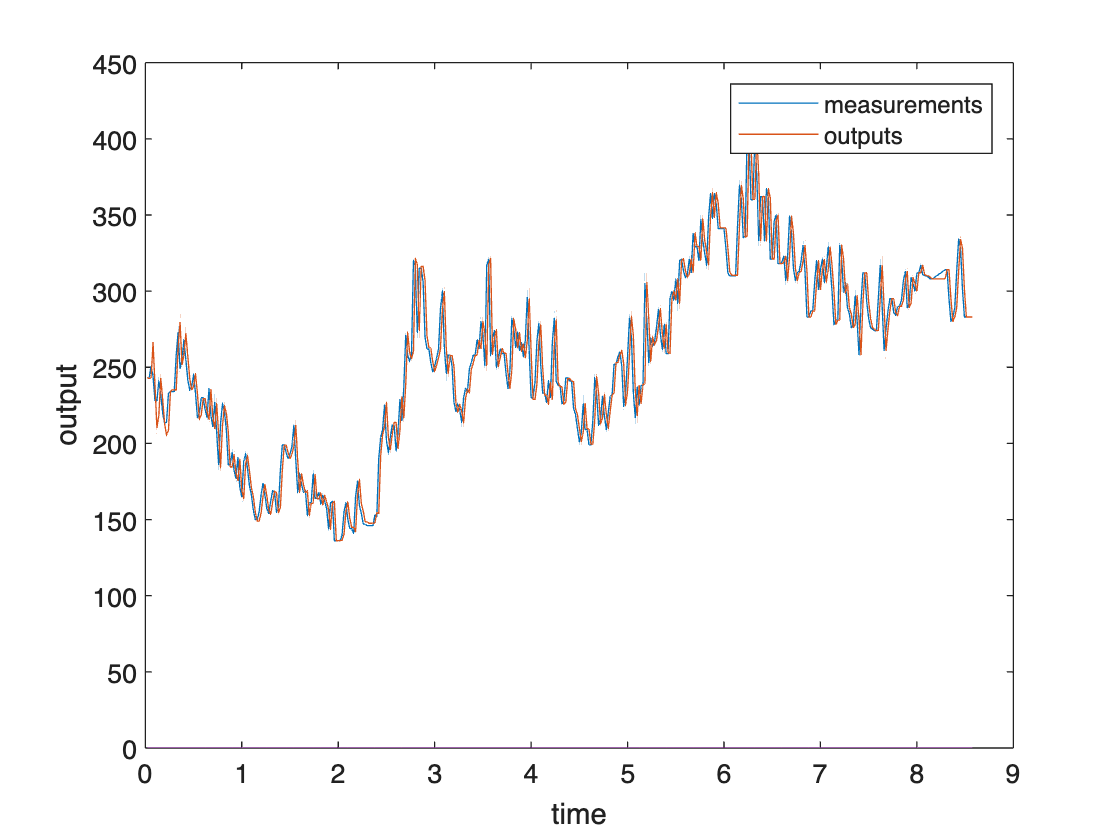

file = readmatrix("/Users/valeriynovytskyy/Desktop/kalman/input.csv");
time = file(:,1);
measurements = file(:, 2);
inputs = file(:, 3);

measurementVariance = 1000;

[outputs, gains] = kalmanFilter( ...
    measurements, ...
    measurementVariance, ...
    inputs ...
);

plot(time, measurements, time, outputs);
xlabel('time');
ylabel('output');
legend('measurements', 'outputs');

function [outputs, gains] = kalmanFilter( ...
    measurements, ...
    measurementVariance, ...
    inputs ...
)
    % Pre-allocate arrays
    outputs = zeros(length(measurements));
    gains = zeros(length(measurements));

    % A weights (3x3 matrix)
    A = [ ...
      1.0005, -0.0050, 0.0001;
      0.0061, 0.9881, -0.0684;
      -0.0009, 0.0768, 0.9224;
    ];
    
    % B weights (3x1 vector)
    B = [ ...
      8.7913e-10;
      1.0489e-07;
      -2.4853e-05;
    ];
    
    % C weights (1x3 vector)
    C = [ ...
      -5.2908e+03, ...
      13.0803, ...
      -0.6389 ...
    ];
    
    % D weight (scalar)
    D = 0;
    
    % K weights (3x1 vector)
    K = [ ...
      -0.0003;
      0.0571;
      -0.3487;
    ];

    % Initial state (3x1 vector)
    x0 = [ ...
      -0.0461;
      -0.0198;
      0.0098;
    ];

    % Initial state variance (3x1 vector)
    dx0 = [ ...
      7.4356e+06;
      3.9306e+09;
      5.1495e+10;
    ];

    % Square identity matrix
    I = eye(length(x0));

    % Noise variance (scalar)
    NoiseVariance = 0.0026;

    % Noise covariance (projected from noise variance)
    Q = I * NoiseVariance;

    % Measurement variance
    R = measurementVariance;

    % Initial state
    x = x0;

    % Initial covariance
    P0 = diag(dx0);
    P = P0;

    for i = 1:length(inputs)
        % Get input
        u = inputs(i);

        % Take measurement
        z = measurements(i);
        
        % Update state
        x = A * x + B * u;

        % Predict
        prediction = C * x + D * u;

        % Update covariance
        P = A * P * A' + Q;
    
        % Optimize gain
        K = (P * C') / (C * P * C' + R);

        % Correct state with measurement
        x = x + K * (z - prediction);

        % Correct covariance
        P = (I - K * C) * P * (I - K * C)' + K * R * K';

        % Output
        outputs(i) = prediction;
        gains(i) = sum(K);
    end
end